syms W_11 W_12 W_13 W_21 W_22 W_23 W_31 W_32 W_33 W_41 W_42 W_43 x_1 x_2 x_3 W_1 W_2 W_3 W_4 real
syms v_1 v_2 v_3 h_1 h_2 h_3 h_4

w = [W_11 W_12 W_13;
    W_21 W_22 W_23;
    W_31 W_32 W_33;
    W_41 W_42 W_43]

$$w = \left(\begin{array}{ccc} W_{11} & W_{12} & W_{13}\\ W_{21} & W_{22} & W_{23}\\ W_{31} & W_{32} & W_{33}\\ W_{41} & W_{42} & W_{43} \end{array}\right)$$

v = [v_1; v_2; v_3]

$$v = \left(\begin{array}{c} v_{1}\\ v_{2}\\ v_{3} \end{array}\right)$$

h = [h_1; h_2; h_3; h_4]

$$h = \left(\begin{array}{c} h_{1}\\ h_{2}\\ h_{3}\\ h_{4} \end{array}\right)$$

b_h = w*v

$$b\_h = \left(\begin{array}{c} W_{11}\,v_{1}+W_{12}\,v_{2}+W_{13}\,v_{3}\\ W_{21}\,v_{1}+W_{22}\,v_{2}+W_{23}\,v_{3}\\ W_{31}\,v_{1}+W_{32}\,v_{2}+W_{33}\,v_{3}\\ W_{41}\,v_{1}+W_{42}\,v_{2}+W_{43}\,v_{3} \end{array}\right)$$

b_v = w'*h

$$b\_v = \left(\begin{array}{c} W_{11}\,h_{1}+W_{21}\,h_{2}+W_{31}\,h_{3}+W_{41}\,h_{4}\\ W_{12}\,h_{1}+W_{22}\,h_{2}+W_{32}\,h_{3}+W_{42}\,h_{4}\\ W_{13}\,h_{1}+W_{23}\,h_{2}+W_{33}\,h_{3}+W_{43}\,h_{4} \end{array}\right)$$

W = [W_1; W_2; W_3];
x = [x_1;x_2;x_3];
W.*x

t = train_input(:,3)
b = w*t-theta

b = 0;
for k=1:2
    b = b + w(3,k)*t(k);
end
b

V = tanh(b);
W(1)*V(1)+W(2)*V(2)+W(3)*V(3)
W*V

mu = randi([1,p]);
x_mu = train_input(:,mu); % randomly pick an input from training set
t_mu = target(mu);

% propagate forward
b_mu = w*x_mu-theta;
V = tanh(b_mu);  % activation function g = tanh()
B_mu = dot(W,V)-Theta;
Out = tanh(B_mu)
diff(tanh(B_mu))

syms x real
f = tanh(x);
diff(f)
g = eval(subs(diff(f),0.03))

B_m = B_mu
t_m = target(mu);
Out_m = Out;
g_prime = eval(subs(diff(f), B_m))
Delta_m = (t_m-Out_m) * g_prime;
delta_W = eta * Delta_m * V'
W = W + delta_W

B = B_mu
t = target(mu);
g_prime_B = eval(subs(diff(f), B))
Delta = (t - Out) * g_prime;
delta_W = eta * Delta * V';
W = W + delta_W;

% assume m=1
delta_w = zeros(size(w));
delta_theta = zeros(size(theta));
for n = 1:N
    x_n = x_mu(n);
    for m = 1:M
        b_m = b_mu(m);
        g_prime_b_m = (1-tanh(b_m)^2);
        delta_m = Delta * W(m) * g_prime_b_m;
        delta_theta(m) = -eta * delta_m;
        delta_w(m,n) = eta * delta_m * x_n;
    end
end
delta_w

delta_w = 1.0e-08 *

    0.0001   -0.0001
    0.0536   -0.0636
    0.0002   -0.0003
    0.2268   -0.2691


tanh(b_mu)

ans =    -0.9999
    0.9574
   -0.9998
    0.8861


tanh(b_mu).^2

ans =     0.9999
    0.9166
    0.9995
    0.7851


delta = Delta * W'.* (1-tanh(b_mu).^2)

delta = 1.0e-05 *

    0.0001
    0.0548
    0.0002
    0.2321


delta_w = eta * delta * x_mu'

delta_w = 1.0e-08 *

    0.0001   -0.0001
    0.0536   -0.0636
    0.0002   -0.0003
    0.2268   -0.2691


eval(subs(diff(f), b_mu))
delta_m = Delta*W'.*eval(subs(diff(f), b_mu))
delta_w = eta * delta_m *x_mu'

H=[];
H(end+1)=0.1;
H(end+1)=0.4;
H(end+1)=1;
H(end+1)=2;
H(end+1)=3;
H(end+1)=6;
H2 = H;
H = flip(H);
figure
hold on
plot(1:epoch_n,log(H))
plot(1:epoch_n,log(H2))
legend('H\_train','H\_val')
hold off

w;
w*validation_input

ans =     1.3256    1.0417   -0.4245    0.8791   -0.9905   -0.6592   -1.1492   -0.2707   -0.1636    0.0486    1.4509   -0.0206    0.2769    1.1772    0.8320    0.2133    0.4255   -0.9830   -0.7680    1.3593    0.6458    0.5004    0.5318    0.3148   -1.5222   -0.1905   -0.2441   -0.7214   -0.8867    0.4970    0.0041    0.2259   -0.9934    0.2571   -1.2787    0.5021    0.9931    0.7093    1.1739   -1.2341   -0.1873    0.6962    1.4657    1.4949    1.3567   -1.0296   -0.4910    0.8281    0.5617    0.0453
    0.0279    0.1030   -0.1006   -0.0824    0.1442   -0.1410   -0.0527   -0.1582   -0.1099   -0.1825   -0.0743   -0.2016    0.1096   -0.0281    0.1281   -0.1842    0.0649    0.2192   -0.0986   -0.2327   -0.0078   -0.1269   -0.0041    0.1360    0.2398   -0.0984   -0.1939   -0.1222    0.0783   -0.0539   -0.1518    0.1856   -0.0333   -0.1897   -0.1256    0.0277    0.1314   -0.1018    0.1487    0.0782   -0.1199    0.1483   -0.0555   -0.0899   -0.0704    0.0644   -0.1294   -0.0980   -0.0370   

b = w*validation_input-theta

b =     1.5086    1.2247   -0.2415    1.0621   -0.8075   -0.4762   -0.9661   -0.0877    0.0194    0.2316    1.6339    0.1624    0.4599    1.3602    1.0150    0.3963    0.6085   -0.8000   -0.5850    1.5424    0.8288    0.6834    0.7148    0.4978   -1.3392   -0.0075   -0.0611   -0.5384   -0.7037    0.6800    0.1871    0.4089   -0.8104    0.4401   -1.0956    0.6851    1.1761    0.8924    1.3569   -1.0510   -0.0042    0.8793    1.6487    1.6779    1.5398   -0.8465   -0.3080    1.0112    0.7447    0.2283
   -0.2293   -0.1542   -0.3578   -0.3396   -0.1130   -0.3983   -0.3099   -0.4155   -0.3672   -0.4398   -0.3316   -0.4588   -0.1477   -0.2853   -0.1291   -0.4415   -0.1923   -0.0380   -0.3558   -0.4900   -0.2651   -0.3841   -0.2614   -0.1212   -0.0175   -0.3556   -0.4512   -0.3794   -0.1790   -0.3111   -0.4091   -0.0716   -0.2905   -0.4469   -0.3829   -0.2295   -0.1259   -0.3591   -0.1086   -0.1791   -0.3772   -0.1089   -0.3128   -0.3472   -0.3276   -0.1928   -0.3866   -0.3552   -0.2942   -0

V = tanh(b)

V =     0.9067    0.8410   -0.2369    0.7865   -0.6682   -0.4432   -0.7470   -0.0875    0.0194    0.2275    0.9266    0.1610    0.4300    0.8764    0.7678    0.3768    0.5431   -0.6640   -0.5263    0.9125    0.6798    0.5937    0.6137    0.4604   -0.8715   -0.0075   -0.0610   -0.4918   -0.6067    0.5915    0.1849    0.3875   -0.6698    0.4137   -0.7989    0.5948    0.8262    0.7126    0.8757   -0.7822   -0.0042    0.7060    0.9287    0.9326    0.9121   -0.6893   -0.2986    0.7662    0.6320    0.2244
   -0.2254   -0.1530   -0.3433   -0.3271   -0.1125   -0.3785   -0.3004   -0.3931   -0.3515   -0.4135   -0.3200   -0.4291   -0.1466   -0.2778   -0.1284   -0.4148   -0.1900   -0.0380   -0.3415   -0.4542   -0.2591   -0.3663   -0.2556   -0.1206   -0.0175   -0.3414   -0.4229   -0.3622   -0.1771   -0.3015   -0.3877   -0.0715   -0.2826   -0.4194   -0.3652   -0.2256   -0.1252   -0.3444   -0.1081   -0.1772   -0.3602   -0.1085   -0.3029   -0.3339   -0.3164   -0.1905   -0.3685   -0.3410   -0.2860   -0

B = W*V-Theta

B =    -0.7465   -1.2061   -0.5322   -0.5257   -0.6921   -0.8799   -1.1226   -0.6124   -0.3772   -0.6054   -0.5832   -0.6478   -0.6993   -0.4704   -1.2916   -0.6672   -0.4509   -0.7841   -0.8973   -1.4496   -0.2303   -0.6557   -0.1581   -0.9579   -1.1102   -0.3339   -0.7016   -0.8985   -0.4889   -0.2226   -0.5153   -1.2099   -0.9653   -0.7017   -1.1420   -0.2539   -1.3953   -0.6008   -1.5723   -0.8981   -0.4301   -1.3519   -0.5449   -0.6476   -0.5597   -0.6941   -0.7040   -0.6131   -0.1926    0.0518


C = 1/(2*p_val)*sum(abs(validation_target'-sign(B)))

C = 0.1472

tmp = 0;
for mu = 1:p_val
    x_mu = validation_input(:,mu);
    b_mu = w * x_mu - theta;    % [Mx1]
    V = tanh(b_mu);         % activation function g = tanh()
    B_mu = W * V - Theta;  % scalar
    Out = tanh(B_mu);       % scalar
    tmp = tmp + abs(validation_target(mu)-sign(Out));
end
C = 1/(2*p_val)*tmp

C = 0.1472

x1 = [1;1];
x2 = [2;2];
x3 = [3;3];
x = [x1,x2,x3]

x =      1     2     3
     1     2     3


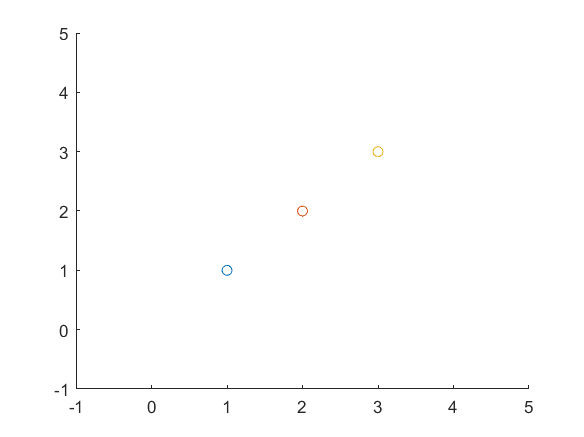

figure
for i =1:3
    scatter(x(1,i), x(2,i))
    xlim([-1,5])
    ylim([-1,5])
    hold on
    pause(1)
end

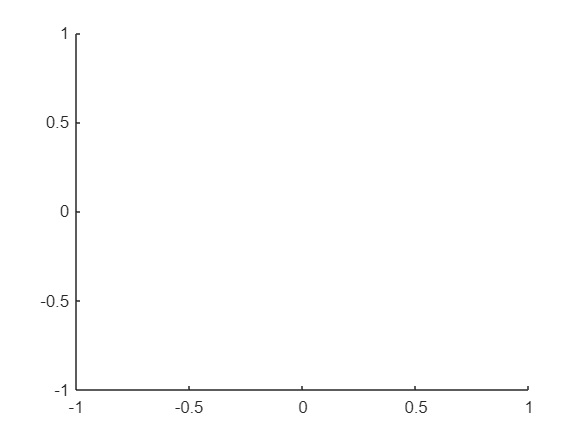

figure
hold on
plot(1,1)
plot(2,2)
xlim([-1,1])
ylim([-1,1])